clear, close all, clc

Tre forskellige typer forsøg udføres, hvor asfaltstyrke testes ved forskellige mængder lufthuller (lav, medium, høj).

Data:

load('dataset_problem_13_13.mat')

a = 3

a = 3

n = 8

n = 8

N = a*n

N = 24

Opgave a/b) Påvirker forskellige mænger lufthuller asfaltens middelværdi? Find P-værdien.

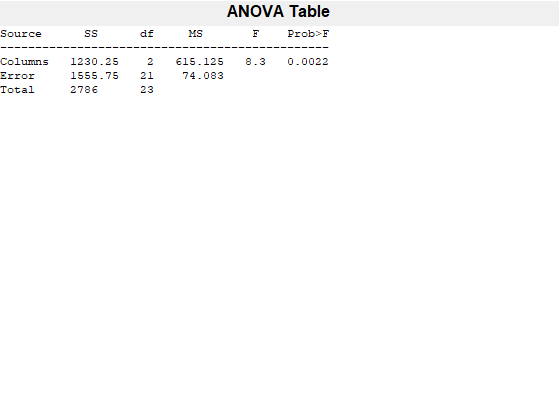

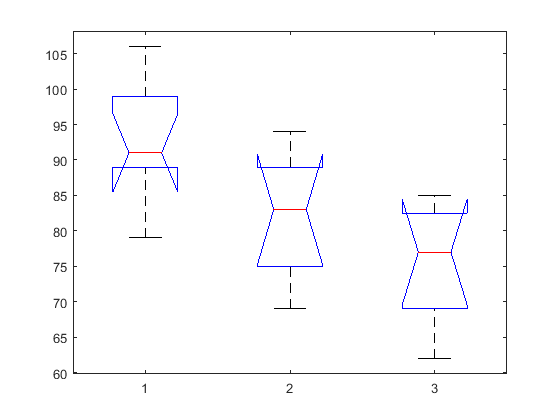

P = 0.0022

TAB = 4×6 cell array
    {'Source' }    {'SS'        }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Columns'}    {[1.2303e+03]}    {[ 2]}    {[615.1250]}    {[  8.3031]}    {[  0.0022]}
    {'Error'  }    {[1.5558e+03]}    {[21]}    {[ 74.0833]}    {0×0 double}    {0×0 double}
    {'Total'  }    {[      2786]}    {[23]}    {0×0 double}    {0×0 double}    {0×0 double}


STATS = struct with fields:
    gnames: [3×1 char]
         n: [8 8 8]
    source: 'anova1'
     means: [92.8750 82.1250 75.5000]
        df: 21
         s: 8.6072


alpha = 0.05;
[P,TAB,STATS] = anova1(data)


% Dette er altså mere sjældent end 0.05, og nulhypotesen
% at de er identiske, forkastes.
% Lufthullerne påvirker derfor middelværdien.

Opgave c) Analyser residualerne fra eksperimentet.

R = ANOVAResiduals(data)

R =     8.6250   -6.6250   -2.0000
    0.9583   -9.2917    8.3333
    7.2917    9.0417  -16.3333
   -2.7083    9.0417   -6.3333
   -5.3750   -3.6250    9.0000
   -6.7083   -0.9583    7.6667
   -0.0417    5.7083   -5.6667
   -2.0417   -3.2917    5.3333


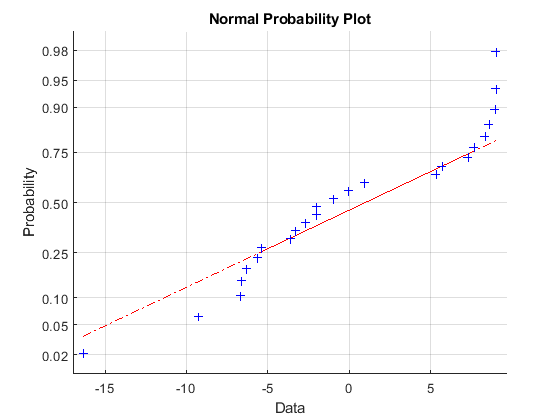

np = [R(:,1);R(:,2);R(:,3)];
normplot(np)

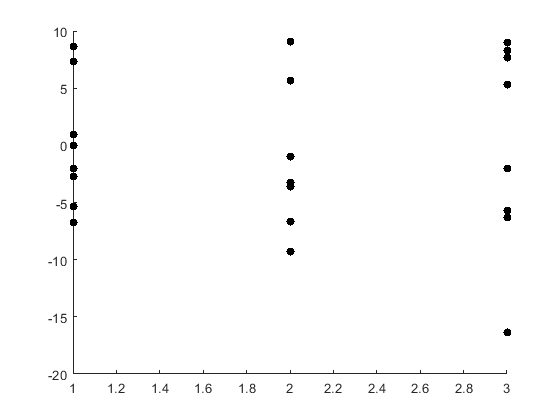

figure(3)
hold on
sz = size(R(:,1));
scatter(ones(sz),R(:,1),'filled','k')
scatter(2*ones(sz),R(:,2),'filled','k')
scatter(3*ones(sz),R(:,3),'filled','k')


% Det lader til, at residualerne ikke er normalfordelte.
% De stiger desuden i størrelse med faktorlevel.

Opgave d) Find et 95%-konfidensniveauinterval over middelværdien, når der er et højt antal lufthuller.

alpha = 0.05;
% Udregnes med: Y_i_bar +- sqrt(SW^2/n_i)*t_N-a,alpha/2
Y3bar = STATS.means(1,3)

Y3bar = 75.5000

S_W_squared = TAB{3,4}

S_W_squared = 74.0833


U = Y3bar + sqrt(S_W_squared/n) * tinv(1-alpha/2,N-a)

U = 81.8285

L = Y3bar + sqrt(S_W_squared/n) * tinv(alpha/2,N-a)

L = 69.1715

Opgave e) Find et 95%-konfidensniveauinterval over forskellen mellem i styrke ved lavt og højt antal lufthuller.

Y1bar = STATS.means(1,1)

Y1bar = 92.8750


% Udregnes med: Y_i_bar - Y_j_bar +- t_N-a,alpha/2 * sqrt(2*SW^2/n)
U = Y1bar-Y3bar + tinv(1-alpha/2,N-a) * sqrt(2*S_W_squared/n)

U = 26.3248

U = Y1bar-Y3bar + tinv(alpha/2,N-a) * sqrt(2*S_W_squared/n)

U = 8.4252


% Altså er de, med 95% sikkerhed, ikke identiske, da
% 0 ikke er med i dette interval.